# 8. ウェーブレット変換による画像近似

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## Haarウェーブレットによる線形近似

まず，ウェーブレット変換において**スケール**という概念を導入しよう．前回までのウェーブレット変換では，**レベル**は1から順に高周波数…低周波数となる数値であった．スケールは逆に，1から順に低周波数…高周波数となるように設定される．ここで，総スケール数 $J$ は、 $n\times n$ の画像に対して


$$\log_2(n) -1$$


となる．ここでスケール $j$が最低周波数成分に対応し，スケール$J$が最高周波数成分に対応する．

HWT係数のうち，指定スケール $j$ （カットオフスケールと呼ぶ）より大きいスケールの係数を0とし（つまり，高周波数成分を取り除き），逆HWTを行うことでHWTによる線形近似画像が得られる．

まず，画像を読み込み，カットオフスケールを設定する．

name = 'house';
u = load_image(name,[]);
n = length(u);
J = log2(n)-1;
Jmin = 0; % 最小スケール数
j = J-1; % カットオフスケール

画像にHWTを適用し，ウェーブレット係数を表示する．

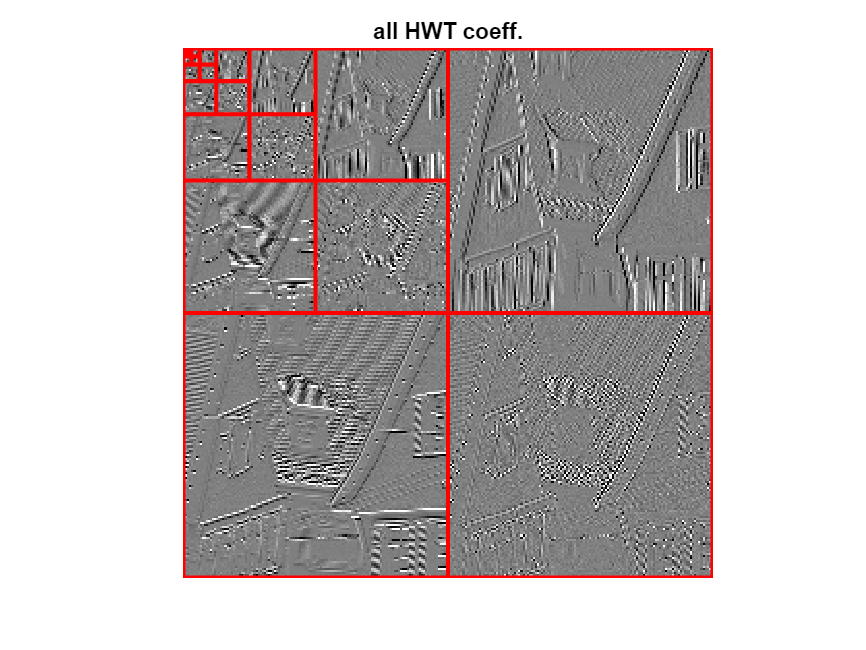

uw = perform_haar_transf(u,Jmin,1); % HWT or IHWT をフルスケールで計算する関数．...
% 3番目の引数を-1にするとIHWTとなる．
plot_wavelet(uw,1); title('all HWT coeff.'); % ウェーブレット係数を表示する関数．

カットオフスケールより大きいスケールの係数を0にしたものを表示する．

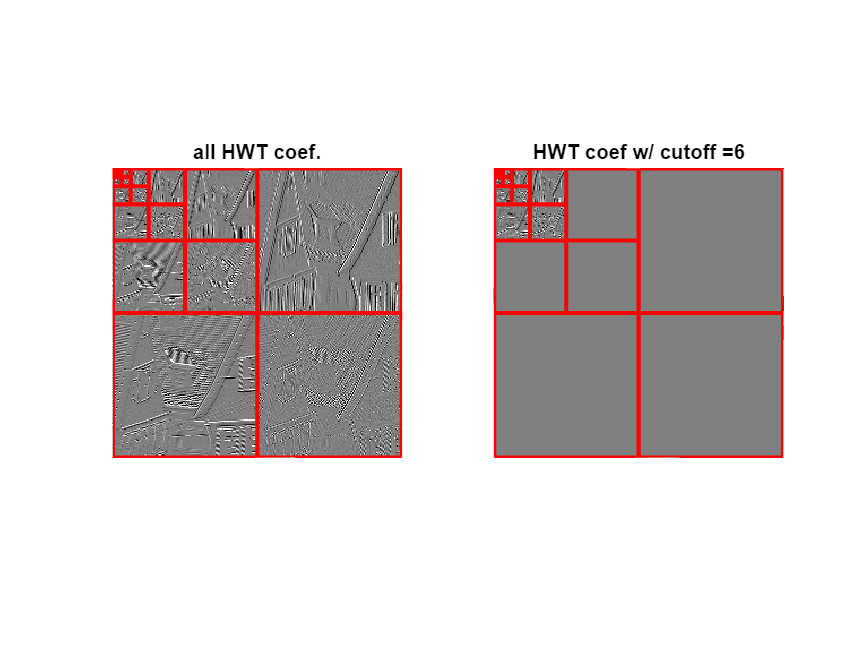

uw1 = zeros(n);
uw1(1:2^j,1:2^j) = uw(1:2^j,1:2^j); % カットオフスケール以下のスケールの係数のみを残す．

figure;
subplot(1,2,1);
plot_wavelet(uw,1); title('all HWT coef.');
subplot(1,2,2);
plot_wavelet(uw1,1); title(['HWT coef w/ cutoff =', num2str(j)]);

IHWTを施して再構成画像（HWT線形近似画像）を得る。

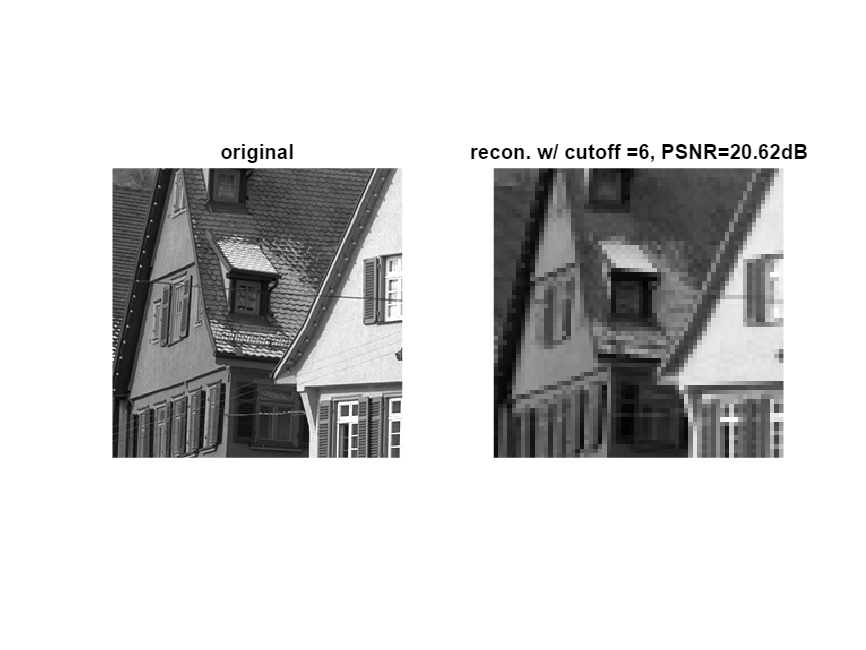

ur1 = perform_haar_transf(uw1,Jmin,-1); % IHWT

figure;
imageplot(u, 'original', 1,2,1);
imageplot(ur1, ['recon. w/ cutoff =', num2str(j),...
    ', PSNR=' num2str(psnr(u,ur1), 4) 'dB'], 1,2,2);

## Haarウェーブレットによる非線形近似

線形近似とは異なり，ウェーブレット係数を絶対値の大きい順に残すことで，非線形ウェーブレット近似が得られる．

しきい値関数を作成する．

S = @(x,T) x .* (abs(x)>T); % Tより大きい係数を残す無名関数．

非線形フーリエ近似と同様にしきい値を設定する．

T = 50;

絶対値がしきい値 $T$ 以下の係数をゼロにする．

uwT = S(uw,T);

しきい値処理された係数を表示する．

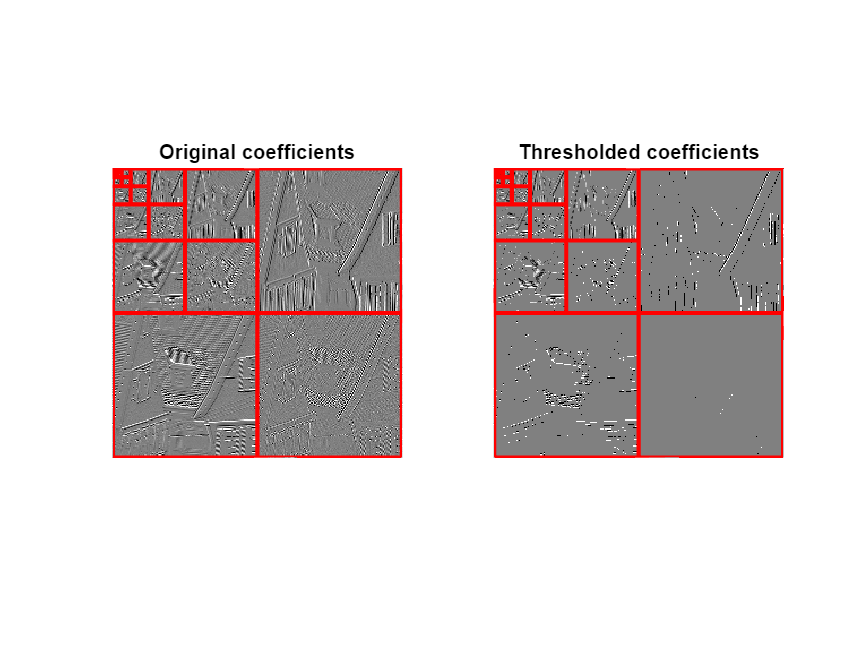

figure;
subplot(1,2,1);
plot_wavelet(uw); axis('tight'); title('Original coefficients');
subplot(1,2,2);
plot_wavelet(uwT); axis('tight'); title('Thresholded coefficients');

IHWTを施して再構成画像（HWT非線形近似画像）を得る．

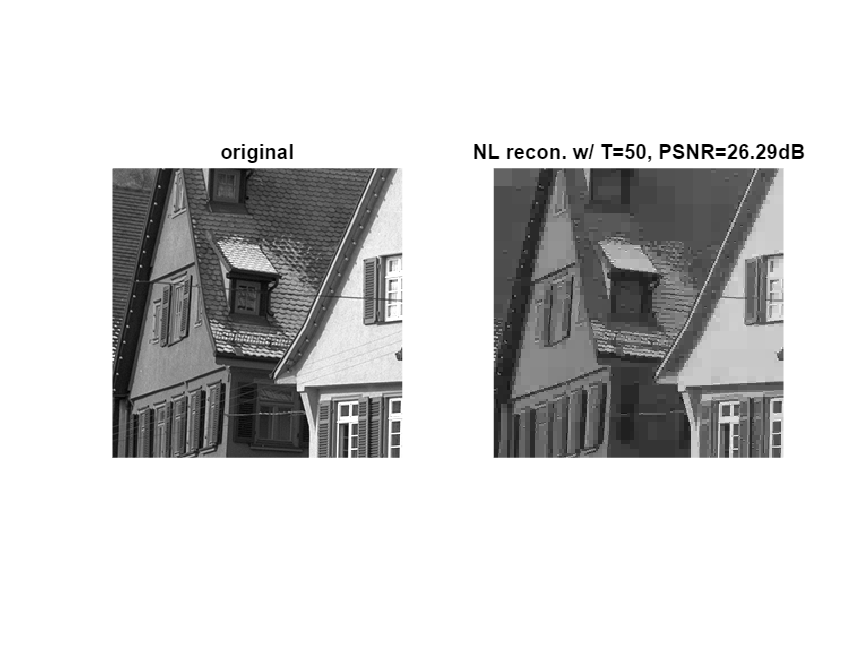

urT = perform_haar_transf(uwT,Jmin,-1);

figure;
imageplot(u, 'original', 1,2,1);
imageplot(urT, ['NL recon. w/ T=', num2str(T),...
    ', PSNR=' num2str(psnr(u,urT), 4) 'dB'], 1,2,2); % NLは non linear の略．

## **演習問題**

**演習6-1**: グレースケール画像'house'を読み込み，フルスケールのHWTを施した上で，カットオフスケールを $j=J,\ldots,1$ まで変化させた際のHWT線形近似画像を求め，原画像とのPSNRとともに $2\times (J+1)/2$ のグリッドに表示せよ（右下のグリッドは空白でOK）．

※ `perform_haar_transf` を使って良い．

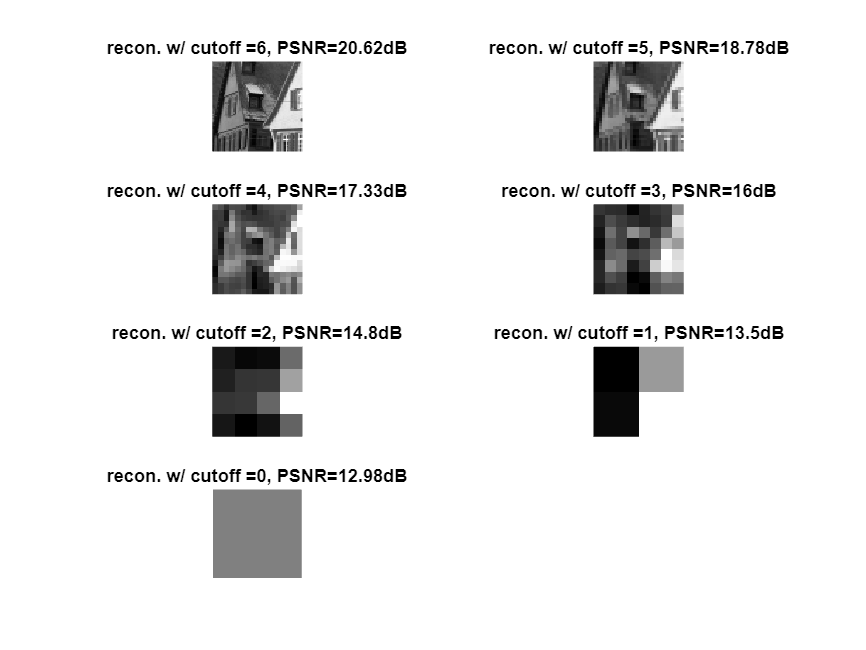

name = 'house';
u = load_image(name,[]);
n = length(u);
J = log2(n)-1;
Jmin = 0; % 最小スケール数
j = J-1; % カットオフスケール
figure;
while j >= 0
    uw = perform_haar_transf(u,Jmin,1); % HWT or IHWT をフルスケールで計算する関数．...
    % 3番目の引数を-1にするとIHWTとなる．
    uw1 = zeros(n);
    uw1(1:2^j,1:2^j) = uw(1:2^j,1:2^j); % カットオフスケール以下のスケールの係数のみを残す．

    ur1 = perform_haar_transf(uw1,Jmin,-1); % IHWT

    imageplot(ur1, ['recon. w/ cutoff =', num2str(j),', PSNR=' num2str(psnr(u,ur1), 4) 'dB'], 4,2,J-j);

    j = j-1;
end

**演習6-2**: グレースケール画像'house'を読み込み，HWTを利用した非線形近似を行う．残す非零係数の数 $M$ を画素数の $1/2, 1/4, 1/8, 1/16, 1/32, 1/64$ に設定した場合のしきい値 $T$ を計算せよ．また，各 $M$ に関して，

- $M$ と対応するしきい値 $T$ と残した $M$ 個のHWT係数（"`plot_wavelet(uw,1)`"を使うとよい）

- HWT非線形近似画像とその PSNR [dB]

をそれぞれ $2\times 3$ のグリッドに表示せよ（係数と近似画像を別々のグリッドにという意味）． `imageplot の引数`を用いるとよい．

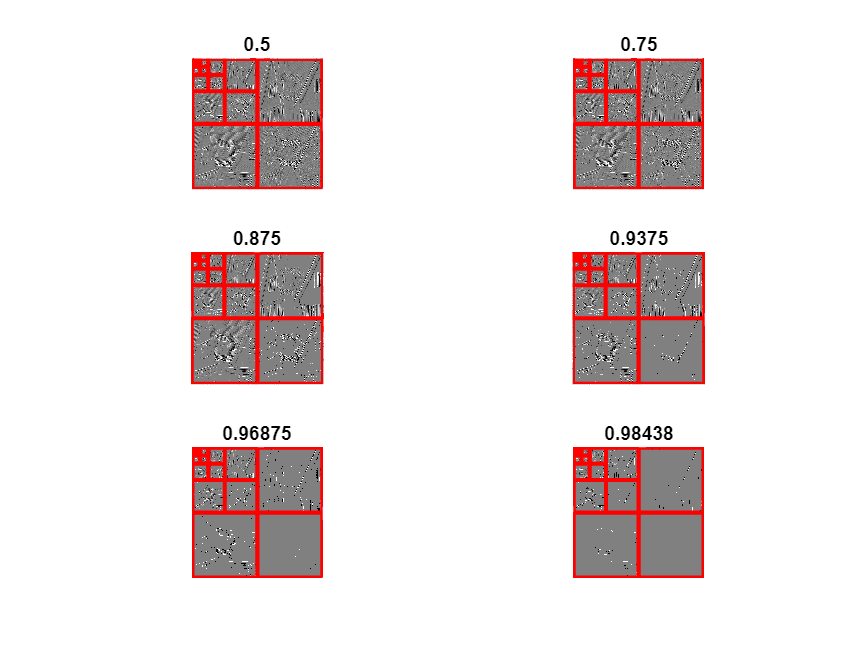

S = @(x,T) x .* (abs(x)>T); % Tより大きい係数を残す無名関数．

name = 'house';
u = load_image(name,[]);
n = length(u);
J = log2(n)-1;
Jmin = 0; % 最小スケール数
j = J-1; % カットオフスケール
figure;
uw = perform_haar_transf(u,Jmin,1); 

for  i = 1:6
    T = quantile(uw(:), 1 - 1/2^i);
    uwT = S(uw,T);

    subplot(3,2,i);
    plot_wavelet(uwT); axis('tight'); title(num2str(1 - 1/2^i));

end

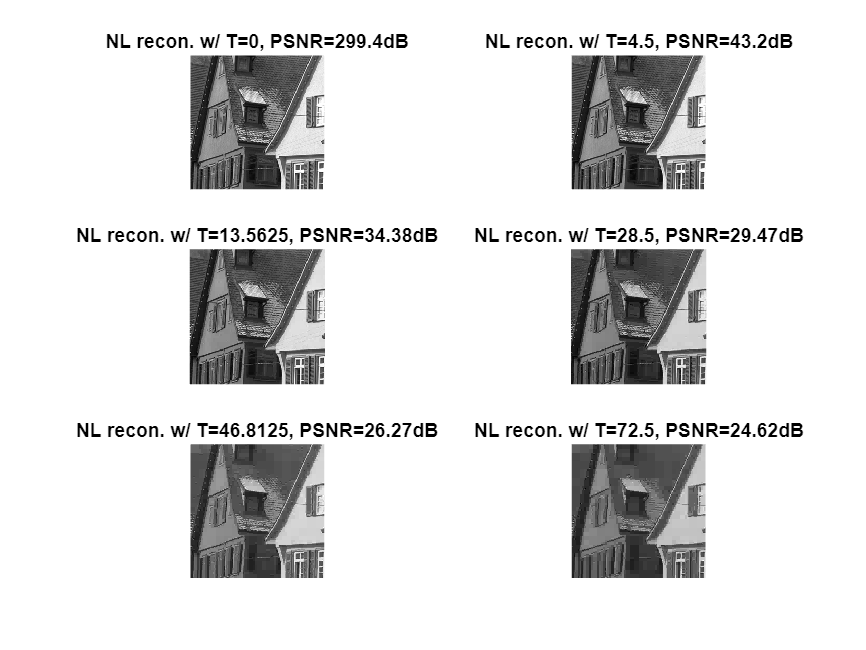


figure;
for  i = 1:6
    T = quantile(uw(:), 1 - 1/2^i);
    uwT = S(uw,T);

    urT = perform_haar_transf(uwT,Jmin,-1);

    imageplot(urT, ['NL recon. w/ T=', num2str(T),', PSNR=' num2str(psnr(u,urT), 4) 'dB'], 3,2,i);

end